## МВИ

Программа H-поляризация МВИ для цилиндра круглого сечения

08_10_20

close all;
clear variables;

f01 = fopen('I_MAS_elips_pres.dat','w');
f02 = fopen('DA_MAS_elips_pres.dat','w');

Входные параметры


% global N a b a1

N = 400;
% 
% % полуоси элипса
a = 2; %большшая полуось - ОX
b = 1; %меньшая полуось - ОZ

f = sqrt(a^2 - b^2);

a1 = 1.8;  
b1 = sqrt(a1^2 - f^2); 
% b1 = 0.9; 

delta_phi = 360/N;
k = 2*pi; 
phi_grad = 60; % угол падения волны [град]

Генерация точек элипса

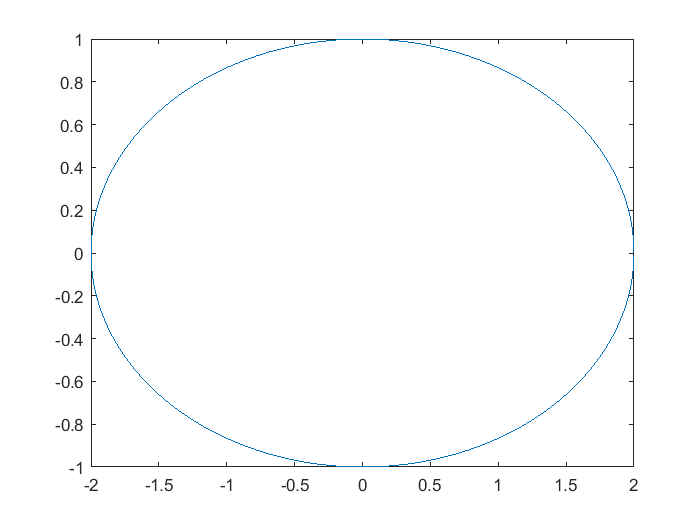

delta_phi = 360/N;
x = zeros(1,N);
z = zeros(1,N);

for i = 1 : N
    x(i) = a*cosd(delta_phi*(i-1));
    z(i) = b*sind(delta_phi*(i-1));
end

plot(x,z)

Генерация точек контура для ВИ

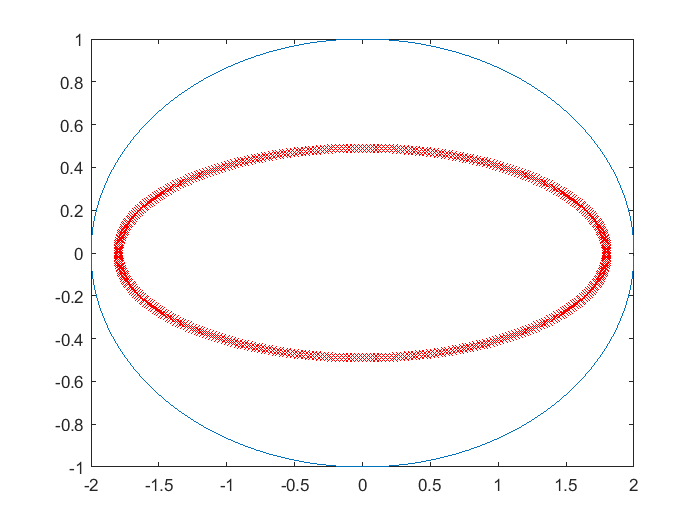

for i = 1 : N
    xAS(i) = a1*cosd(delta_phi*(i-1));
    zAS(i) = b1*sind(delta_phi*(i-1));
end

plot(x,z, xAS,zAS, 'xr')

Касательная к основному элипсу

for i = 1 : N
    tx(i) = -a^2*z(i)/sqrt(a^4*z(i)^2+b^4*x(i)^2);
    tz(i) =  b^2*x(i)/sqrt(a^4*z(i)^2+b^4*x(i)^2);
end

% compass(tx(2),tz(2))

Изучим один цикл

% count = 0;
% пробегаемся по всем точкам оснвого элипса
for m = 1 : N
    xm = x(m);
    zm = z(m);
    txm = tx(m);
    tzm = tz(m);
    
    %пробегаемся по всем точкам ВИ
    for n = 1 : N
        xn = xAS(n);
        zn = zAS(n);
        
        % Растояние между m и n
        dx = xm - xn;
        dz = zm - zn;
        r = sqrt(dx^2 + dz^2);

        Es(m,n) = besselh(1,1,k*r)*(dx*tzm - dz*txm)/r;         
        
    end
end
 

Расчет падающего поля

for m=1:N
    cx = -1i*k*cosd(phi_grad);
    cz = -1i*k*sind(phi_grad);
    % Определим координаты
    xm = x(m);
    zm = z(m);
    txm = tx(m);
    tzm = tz(m);
    
%   Итоговое падающее поел - это суперпозиция полей
    Eix = +1i*sind(phi_grad)*exp(cx*xm+cz*zm);% падающее поле X
    Eiz = -1i*cosd(phi_grad)*exp(cx*xm+cz*zm);% падающее поле Z
    Ei(m,1) = Eix*txm + Eiz*tzm;         
end


Посчитаем токи и построим график

% расчеток токов ВИ 
I=Es\Ei;


for m = 1 : N
    xm = x(m);
    zm = z(m);
    txm = tx(m);
    tzm = tz(m);
    
    %пробегаемся по всем точкам ВИ
    sum_count = 0;
    for n = 1 : N
        xn = xAS(n);
        zn = zAS(n);    
    
        % Растояние между m и n
        xmn = (xm - xn);
        zmn = (zm - zn);
        r = sqrt(xmn^2 + zmn^2);
        
        Hs = I(n)*besselh(0, 1, k*r);
       
        sum_count = sum_count + Hs;
    end
    
    cx = -1i*k*cosd(phi_grad);
    cz = -1i*k*sind(phi_grad);
    Hi = exp(cx*xm+cz*zm); 
   
    I_real(m,1) = sum_count + Hi;
end

Сделаем счетчик для графика в градусах

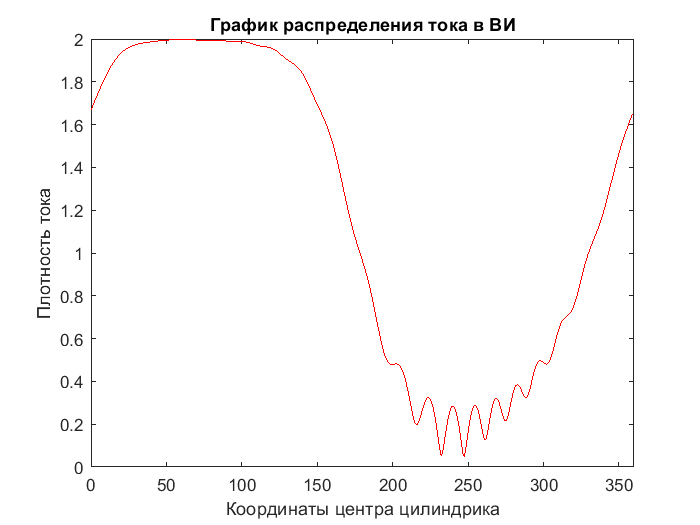

% Берем угол точки в середине отрезка
begin_phi = delta_phi/2;
phi_for_graf = [];
for i = 1 : N 
    count = delta_phi*(i-1);
    phi_for_graf(i) = count;
end

figure;
fig = plot(phi_for_graf, abs(I_real), 'r');
title('График распределения тока в ВИ'); 
xlabel('Координаты центра цилиндрика'); 
xlim([0 360])
ylabel('Плотность тока');

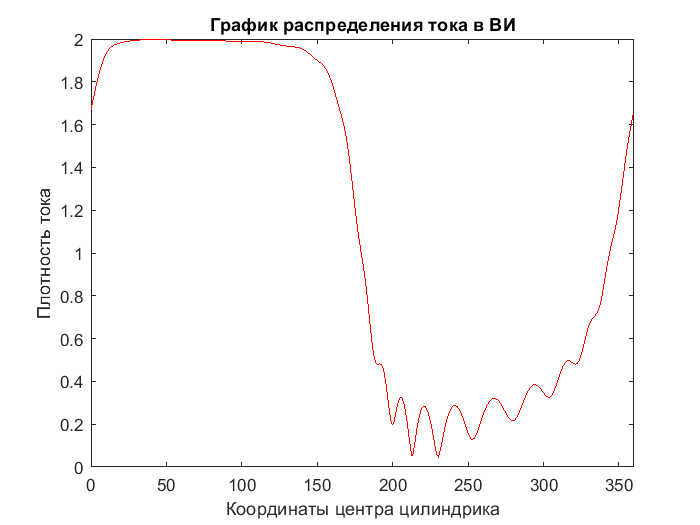

for i = 1 : N
    z_m = z(i);
    x_m = x(i);
    
    if (x_m <= 0 && z_m < 0) || (x_m >= 0 && z_m < 0)
        phi_for_graf_real(i) = atan2(z_m, x_m)*180/pi+360;
    else
        phi_for_graf_real(i) = atan2(z_m, x_m)*180/pi;
    end
    
%     if (x_m > 0 && z_m >= 0)
%         phi_for_graf_real(i) = atan(z_m/x_m)*180/pi;
%     elseif (x_m <= 0 && z_m > 0)
%         phi_for_graf_real(i) = atan(z_m/x_m)*180/pi+180;
%     elseif (x_m < 0 && z_m <= 0)
%         phi_for_graf_real(i) = atan(z_m/x_m)*180/pi+180;    
%     elseif (x_m >= 0 && z_m < 0)
%         phi_for_graf_real(i) = atan(z_m/x_m)*180/pi+360;    
%     end

end

figure;
fig = plot(phi_for_graf_real, abs(I_real), 'r');
title('График распределения тока в ВИ'); 
xlabel('Координаты центра цилиндрика'); 
xlim([0 360])
ylabel('Плотность тока');

Запись в файл

for n = 1 : N
    fprintf(f01,' %10.5f %10.5f\n', phi_for_graf_real(n), abs(I_real(n)));
end
fclose(f01);

## ЭПР

for p = 1 : 721
    Sum_H = 0;
    phi = (p-1)/2; % угол из формулы для приведения 721 к 360 градусам
    phi_for_graf_DA(p) = (p-1)/2; % угол для графика
    
    cx = - 1i*k*cosd(phi);
    cz = - 1i*k*sind(phi);

    for n = 1 : N
       Sum_H = Sum_H + I(n)*exp(cx*xAS(n)+cz*zAS(n)); 
    end
    
    RCS(p) = 10*log10((2/pi)*Sum_H*conj(Sum_H));

end

% график поля в дальней зоне от угла налюденя (не нормированный)
figure;
plot(phi_for_graf_DA ,RCS,'r-');

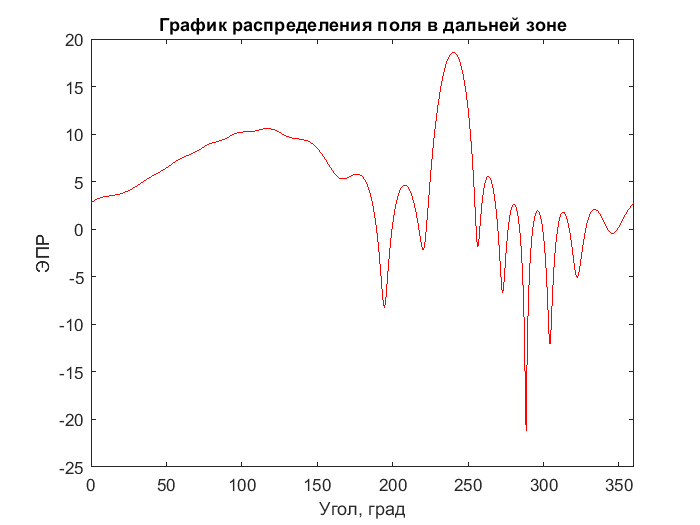

title('График распределения поля в дальней зоне'); 
xlim([0 360])
xlabel('Угол, град'); 
ylabel('ЭПР');

Запись в файл

for p = 1 : 721
    fprintf(f02,' %10.5f %10.5f\n', phi_for_graf_DA(p), RCS(p));
end
fclose(f02);